% 1. Задайте уровни рождаемости (b%), смертности (dC%, dA%) и начальное распределение населения N1, N2, N3, N4.

% Рассмотрены данные для населения Нидерландов
% Информация с сайтов https://www.macrotrends.net/countries/NLD/netherlands/population и https://www.indexmundi.com/netherlands/age_structure.html

b = 1.83; 
dc = 0.2; 
da = 0.75; 
N1 = 943187; % 0 – 5 лет
N2 = 2932312; % 6 – 19 лет
N3 = 9005069; % 20 – 59 лет
N4 = 1539419; % 60 – 69 лет

% 2. Постройте преобразования, описывающие эволюцию этой модели населения.

L = [ (1 - dc/100)*5/6, 0, b/100, 0; 
      (1 - dc/100)*1/6, 13/14, 0, 0;
      0, 1/14, 39/40, 0;
      0, 0, 1/40, (1 - da/100)*9/10 ];

% 3. Спрогнозируйте распределение населения по группам в течение 100 лет.

N = [N1; N2; N3; N4];
for n = 1:100
    N(:, n + 1) = L * N(:, n);
end

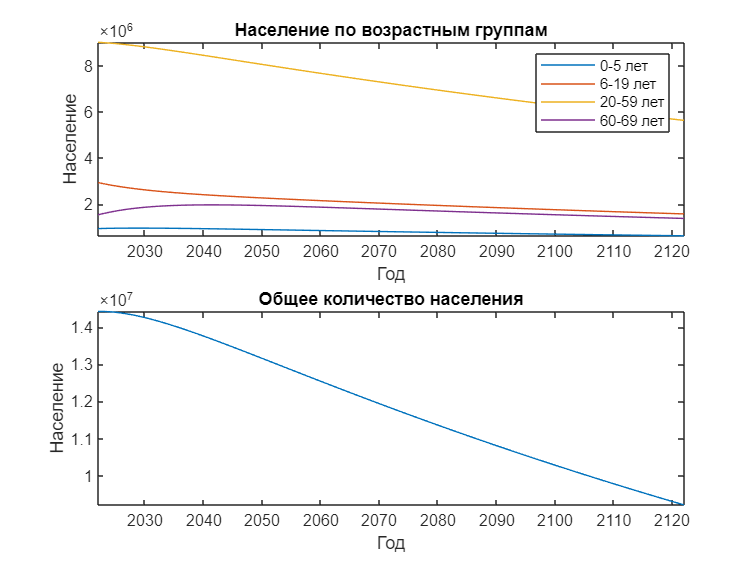

% 4. Постойте графики распределения населения по группам и общего количества населения в течение 100 лет.

years = 2022:2122;

subplot(2,1,1)
plot(years, N)
title('Население по возрастным группам')
xlabel('Год')
ylabel('Население')
legend('0-5 лет', '6-19 лет', '20-59 лет', '60-69 лет')
axis tight

subplot(2,1,2)
plot(years,sum(N))
title('Общее количество населения')
xlabel('Год')
ylabel('Население')
axis tight

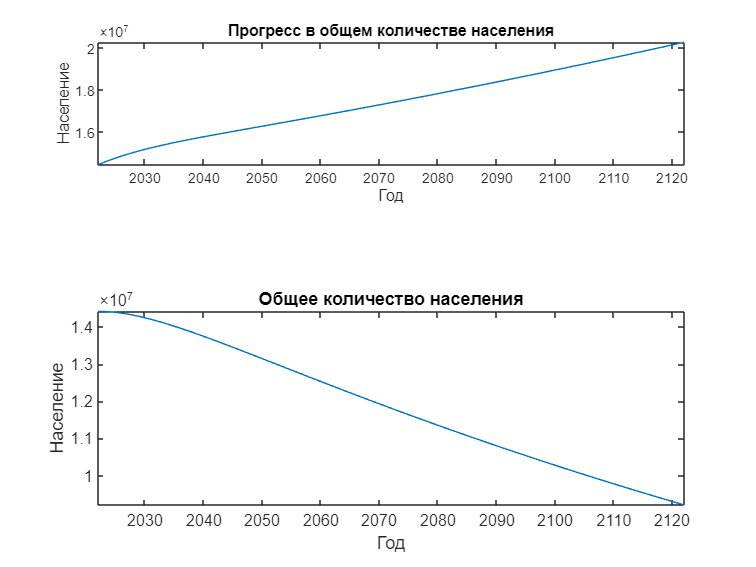

% 5. Подберите параметры т.о., чтобы наблюдался:
% a. Прогресс,
% b. Стабильность,
% c. Регресс
    % i. Общего количества населения;
    % ii. По группам;
    % iii. Трудоспособного населения.

b = 3; 
dc = 0.1; 
da = 0.1;

L = [ (1 - dc/100)*5/6, 0, b/100, 0; 
      (1 - dc/100)*1/6, 13/14, 0, 0;
      0, 1/14, 39/40, 0;
      0, 0, 1/40, (1 - da/100)*9/10 ];
for n = 1:100
    N(:, n + 1) = L * N(:, n);
end

years = 2022:2122;
subplot(3,1,1)
plot(years,sum(N))
title('Прогресс в общем количестве населения')
xlabel('Год')
ylabel('Население')
axis tight

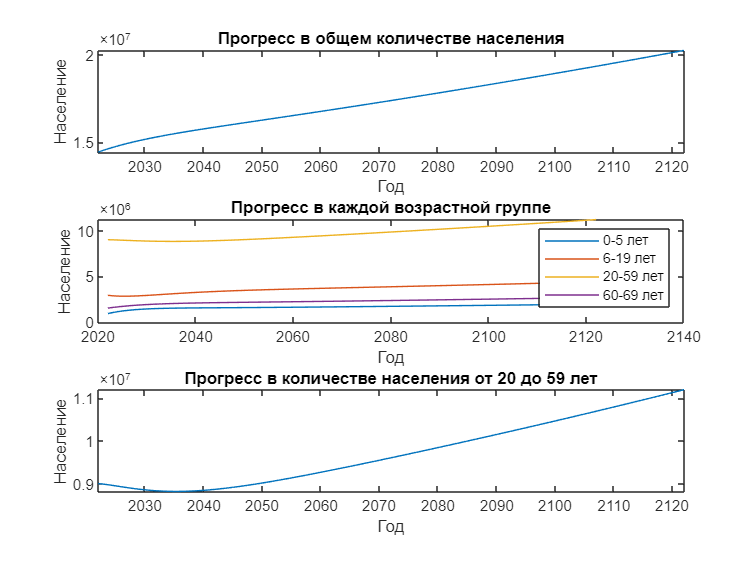


subplot(3,1,2)
plot(years, N)
title('Прогресс в каждой возрастной группе')
xlabel('Год')
ylabel('Население')
legend('0-5 лет', '6-19 лет', '20-59 лет', '60-69 лет')

subplot(3,1,3)
plot(years, N(3, :))
title('Прогресс в количестве населения от 20 до 59 лет')
xlabel('Год')
ylabel('Население')
axis tight

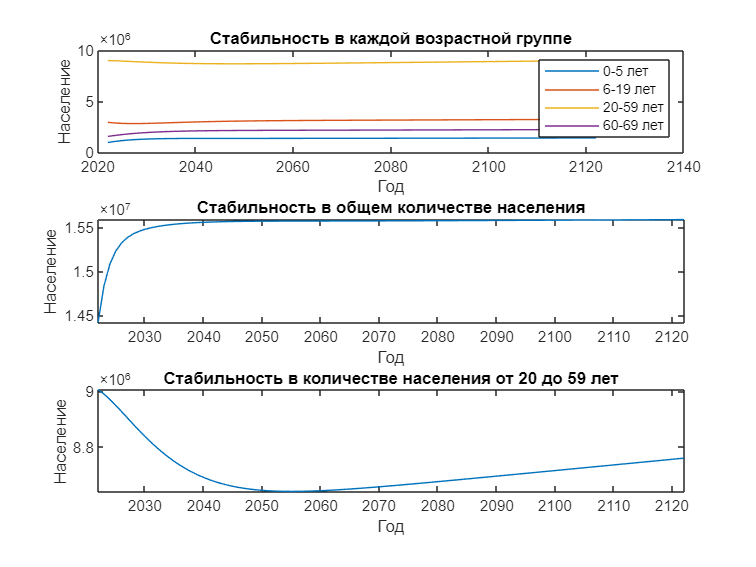

% Стабильность в каждой возрастной группе
b = 2.6; 
dc = 0.1; 
da = 0.1; 

L = [ (1 - dc/100)*5/6, 0, b/100, 0; 
      (1 - dc/100)*1/6, 13/14, 0, 0;
      0, 1/14, 39/40, 0;
      0, 0, 1/40, (1 - da/100)*9/10 ];

for n = 1:100
    N(:, n + 1) = L * N(:, n);
end

subplot(3,1,1)
plot(years, N)
title('Стабильность в каждой возрастной группе')
xlabel('Год')
ylabel('Население')
legend('0-5 лет', '6-19 лет', '20-59 лет', '60-69 лет')

% Стабильность в общем количестве населения
b = 10; % коэффициент рождаемости
dc = 33.3; % коэффициент детской смертности
da = 1.4;

L = [ (1 - dc/100)*5/6, 0, b/100, 0; 
      (1 - dc/100)*1/6, 13/14, 0, 0;
      0, 1/14, 39/40, 0;
      0, 0, 1/40, (1 - da/100)*9/10 ];

for n = 1:100
    N(:, n + 1) = L * N(:, n);
end

subplot(3,1,2)
plot(years,sum(N))
title('Стабильность в общем количестве населения')
xlabel('Год')
ylabel('Население')
axis tight

% Стабильность в количестве трудоспособного населения
b = 2.55; 
dc = 0.1; 
da = 2.55; 

L = [ (1 - dc/100)*5/6, 0, b/100, 0; 
      (1 - dc/100)*1/6, 13/14, 0, 0;
      0, 1/14, 39/40, 0;
      0, 0, 1/40, (1 - da/100)*9/10 ];

for n = 1:100
    N(:, n + 1) = L * N(:, n);
end

subplot(3,1,3)
plot(years, N(3, :))
title('Стабильность в количестве населения от 20 до 59 лет')
xlabel('Год')
ylabel('Население')
axis tight

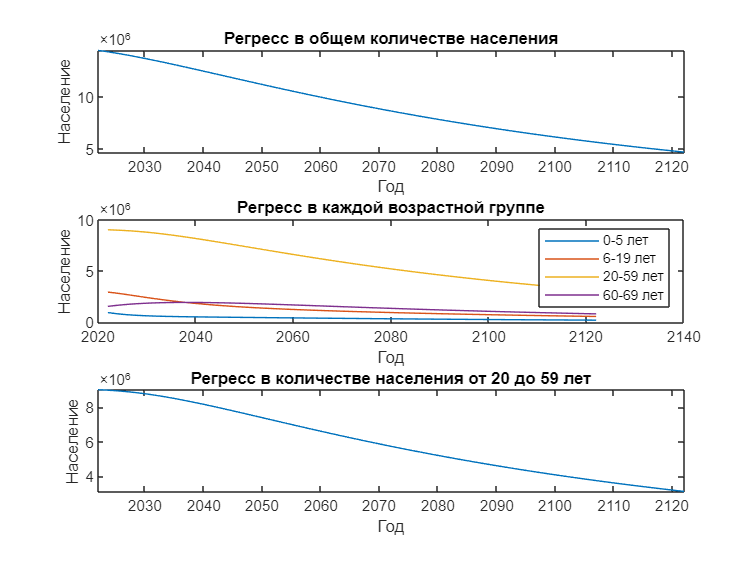

b = 1; 
dc = 0.22; 
da = 0.89; 

L = [ (1 - dc/100)*5/6, 0, b/100, 0; 
      (1 - dc/100)*1/6, 13/14, 0, 0;
      0, 1/14, 39/40, 0;
      0, 0, 1/40, (1 - da/100)*9/10 ];

for n = 1:100
    N(:, n + 1) = L * N(:, n);
end

years = 2022:2122;
subplot(3,1,1)
plot(years,sum(N))
title('Регресс в общем количестве населения')
xlabel('Год')
ylabel('Население')
axis tight

subplot(3,1,2)
plot(years, N)
title('Регресс в каждой возрастной группе')
xlabel('Год')
ylabel('Население')
legend('0-5 лет', '6-19 лет', '20-59 лет', '60-69 лет')

subplot(3,1,3)
plot(years, N(3, :))
title('Регресс в количестве населения от 20 до 59 лет')
xlabel('Год')
ylabel('Население')
axis tight